Image Compression

9.) Write a function that returns the matrix **S** of any given size. Write this yourself. Do not simply use a built-in MATLAB function.

%Create an empty array
S_dum = zeros(5)

S_dum =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



%Initialize n
n = length(S_dum)

n = 5


%Now calcualte values of S and input them into the array X containing zeros
for i = 1:length(S_dum(1,:)) %Rows
    for j = 1:length(S_dum(:,1)) %Columns
        S_dum(i,j) = sqrt(2/n) * sin((pi*(i - 0.5)*(j - 0.5)) / n); %Discrete Sine Transform
    end
end
S_dum

S_dum =     0.0989    0.2871    0.4472    0.5635    0.6247
    0.2871    0.6247    0.4472   -0.0989   -0.5635
    0.4472    0.4472   -0.4472   -0.4472    0.4472
    0.5635   -0.0989   -0.4472    0.6247   -0.2871
    0.6247   -0.5635    0.4472   -0.2871    0.0989


10.  Verify that, for the5×5 matrix S,S=S`−1`. That is, show that SS=I`5 `(this can be done in MATLAB).

%Verify that S = S^-1 (S inverse)
S_inverse = S_dum^(-1) %S inverse

S_inverse =     0.0989    0.2871    0.4472    0.5635    0.6247
    0.2871    0.6247    0.4472   -0.0989   -0.5635
    0.4472    0.4472   -0.4472   -0.4472    0.4472
    0.5635   -0.0989   -0.4472    0.6247   -0.2871
    0.6247   -0.5635    0.4472   -0.2871    0.0989



%Now verify that S * S^(-1) is equal to identity matrix
I = S_dum * S_inverse

I =     1.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0000    1.0000   -0.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    1.0000


11. In this problem we need to calculate the 2D DST 

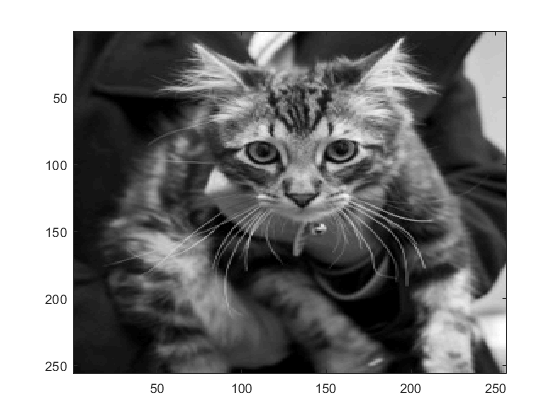

%Define the 2D DST
%First we need to read in the image
img_read = imread('photo2.jpg'); %Read in the images
img_double = double(img_read); %Convert the img_read variable into a double datatype
X_g = 0.3*img_double(:,:,1) + 0.3*img_double(:,:,2) + 0.3*img_double(:,:,3);%Convert the 3D matrix into a 2D matrix this will be X_g
imagesc(uint8(X_g));%Output the grayscale image
colormap('gray');


%Now we can define the 2D DST
Y = DSTfunction(X_g) * X_g * transpose(DSTfunction(X_g))

S =     0.0003    0.0008    0.0014    0.0019    0.0024    0.0030    0.0035    0.0041    0.0046    0.0051    0.0057    0.0062    0.0068    0.0073    0.0079    0.0084    0.0089    0.0095    0.0100    0.0106    0.0111    0.0116    0.0122    0.0127    0.0132    0.0138    0.0143    0.0148    0.0154    0.0159    0.0164    0.0170    0.0175    0.0180    0.0186    0.0191    0.0196    0.0202    0.0207    0.0212    0.0217    0.0223    0.0228    0.0233    0.0238    0.0244    0.0249    0.0254    0.0259    0.0264
    0.0008    0.0024    0.0041    0.0057    0.0073    0.0089    0.0106    0.0122    0.0138    0.0154    0.0170    0.0186    0.0202    0.0217    0.0233    0.0249    0.0264    0.0280    0.0295    0.0311    0.0326    0.0341    0.0356    0.0371    0.0385    0.0400    0.0414    0.0429    0.0443    0.0457    0.0471    0.0484    0.0498    0.0511    0.0524    0.0537    0.0550    0.0563    0.0575    0.0588    0.0600    0.0611    0.0623    0.0635    0.0646    0.0657    0.0668    0.0678    0.0688    0

S =     0.0003    0.0008    0.0014    0.0019    0.0024    0.0030    0.0035    0.0041    0.0046    0.0051    0.0057    0.0062    0.0068    0.0073    0.0079    0.0084    0.0089    0.0095    0.0100    0.0106    0.0111    0.0116    0.0122    0.0127    0.0132    0.0138    0.0143    0.0148    0.0154    0.0159    0.0164    0.0170    0.0175    0.0180    0.0186    0.0191    0.0196    0.0202    0.0207    0.0212    0.0217    0.0223    0.0228    0.0233    0.0238    0.0244    0.0249    0.0254    0.0259    0.0264
    0.0008    0.0024    0.0041    0.0057    0.0073    0.0089    0.0106    0.0122    0.0138    0.0154    0.0170    0.0186    0.0202    0.0217    0.0233    0.0249    0.0264    0.0280    0.0295    0.0311    0.0326    0.0341    0.0356    0.0371    0.0385    0.0400    0.0414    0.0429    0.0443    0.0457    0.0471    0.0484    0.0498    0.0511    0.0524    0.0537    0.0550    0.0563    0.0575    0.0588    0.0600    0.0611    0.0623    0.0635    0.0646    0.0657    0.0668    0.0678    0.0688    0

Y = 	1.0e+04 *

    1.5879    0.2846    0.3781   -0.0395    0.0667   -0.1129   -0.0920    0.1416   -0.0480    0.0432    0.0613   -0.0601    0.0926   -0.0461    0.0964   -0.0185    0.0343   -0.0325    0.0456   -0.0233    0.0357   -0.0107    0.0234   -0.0021    0.0364    0.0016    0.0165    0.0098   -0.0092    0.0213   -0.0093    0.0185    0.0038    0.0052    0.0175    0.0071    0.0104    0.0022   -0.0045   -0.0001    0.0127   -0.0055    0.0219    0.0073    0.0014   -0.0074    0.0155    0.0038    0.0026    0.0036
    0.7106    0.3655   -0.2514    0.1126    0.0066   -0.0355    0.1871   -0.2280    0.1154   -0.0779   -0.0162    0.0601   -0.0355    0.0744   -0.0494    0.0431   -0.0126   -0.0077    0.0067    0.0140   -0.0292    0.0480   -0.0196    0.0285   -0.0170    0.0236    0.0077   -0.0159    0.0090   -0.0072    0.0060   -0.0181    0.0160    0.0178    0.0101   -0.0090    0.0169   -0.0007   -0.0083   -0.0072    0.0017    0.0003    0.0118    0.0155   -0.0111   -0.0043    0.0063    0.0056   

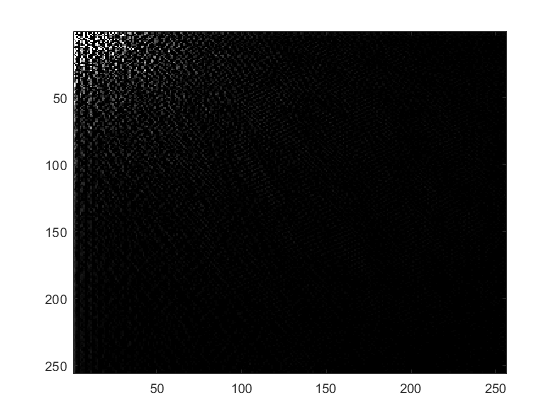

imagesc(uint8(Y));


%Now undo the two dimensional DST
undo_Y =  DSTfunction(X_g)^(-1) * Y * DSTfunction(X_g)

S =     0.0003    0.0008    0.0014    0.0019    0.0024    0.0030    0.0035    0.0041    0.0046    0.0051    0.0057    0.0062    0.0068    0.0073    0.0079    0.0084    0.0089    0.0095    0.0100    0.0106    0.0111    0.0116    0.0122    0.0127    0.0132    0.0138    0.0143    0.0148    0.0154    0.0159    0.0164    0.0170    0.0175    0.0180    0.0186    0.0191    0.0196    0.0202    0.0207    0.0212    0.0217    0.0223    0.0228    0.0233    0.0238    0.0244    0.0249    0.0254    0.0259    0.0264
    0.0008    0.0024    0.0041    0.0057    0.0073    0.0089    0.0106    0.0122    0.0138    0.0154    0.0170    0.0186    0.0202    0.0217    0.0233    0.0249    0.0264    0.0280    0.0295    0.0311    0.0326    0.0341    0.0356    0.0371    0.0385    0.0400    0.0414    0.0429    0.0443    0.0457    0.0471    0.0484    0.0498    0.0511    0.0524    0.0537    0.0550    0.0563    0.0575    0.0588    0.0600    0.0611    0.0623    0.0635    0.0646    0.0657    0.0668    0.0678    0.0688    0

S =     0.0003    0.0008    0.0014    0.0019    0.0024    0.0030    0.0035    0.0041    0.0046    0.0051    0.0057    0.0062    0.0068    0.0073    0.0079    0.0084    0.0089    0.0095    0.0100    0.0106    0.0111    0.0116    0.0122    0.0127    0.0132    0.0138    0.0143    0.0148    0.0154    0.0159    0.0164    0.0170    0.0175    0.0180    0.0186    0.0191    0.0196    0.0202    0.0207    0.0212    0.0217    0.0223    0.0228    0.0233    0.0238    0.0244    0.0249    0.0254    0.0259    0.0264
    0.0008    0.0024    0.0041    0.0057    0.0073    0.0089    0.0106    0.0122    0.0138    0.0154    0.0170    0.0186    0.0202    0.0217    0.0233    0.0249    0.0264    0.0280    0.0295    0.0311    0.0326    0.0341    0.0356    0.0371    0.0385    0.0400    0.0414    0.0429    0.0443    0.0457    0.0471    0.0484    0.0498    0.0511    0.0524    0.0537    0.0550    0.0563    0.0575    0.0588    0.0600    0.0611    0.0623    0.0635    0.0646    0.0657    0.0668    0.0678    0.0688    0

undo_Y =    28.8000   32.4000   34.2000   34.2000   33.3000   33.3000   34.2000   35.1000   33.9000   31.2000   27.6000   24.9000   21.3000   17.7000   15.9000   15.0000   13.2000   13.2000   12.3000   13.2000   13.2000   13.2000   13.5000   15.3000   17.1000   23.4000   31.5000   36.9000   39.6000   38.7000   36.0000   34.2000   33.6000   35.4000   37.8000   38.7000   39.6000   40.2000   41.4000   40.8000   40.8000   43.2000   45.9000   47.7000   48.6000   47.4000   44.1000   40.8000   39.0000   36.0000
   26.1000   29.7000   33.3000   33.3000   32.4000   33.3000   34.2000   35.1000   33.9000   30.3000   26.7000   23.1000   20.4000   17.7000   15.9000   15.0000   12.3000   12.3000   12.3000   13.2000   13.2000   14.1000   16.2000   18.0000   24.3000   30.6000   37.8000   41.4000   41.4000   39.6000   36.9000   35.1000   36.3000   37.2000   39.6000   40.8000   40.5000   41.1000   41.1000   41.7000   43.5000   45.6000   47.4000   48.0000   47.7000   45.9000   42.3000   40.5000   37.2000

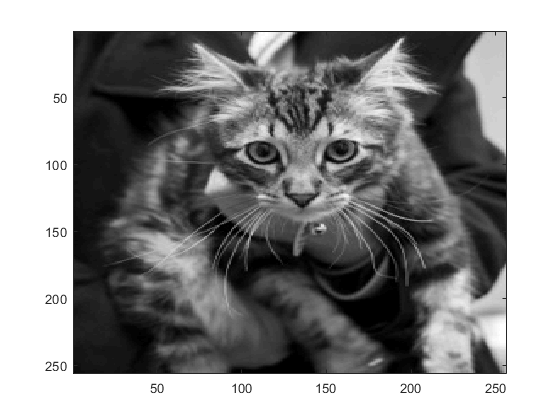


%If the two dimensional matrix is undone then we should obtain the gray
%scale image
imagesc(uint8(undo_Y))

12. Perform compression

%Apply compression algo
p = 0.15;

%Delete some of the less important values in the transformed matrix
compress = DSTcompress(Y,p)

C = 	1.0e+04 *

    1.5879    0.2846    0.3781   -0.0395    0.0667   -0.1129   -0.0920    0.1416   -0.0480    0.0432    0.0613   -0.0601    0.0926   -0.0461    0.0964   -0.0185    0.0343   -0.0325    0.0456   -0.0233    0.0357   -0.0107    0.0234   -0.0021    0.0364    0.0016    0.0165    0.0098   -0.0092    0.0213   -0.0093    0.0185    0.0038    0.0052    0.0175    0.0071    0.0104    0.0022   -0.0045   -0.0001    0.0127   -0.0055    0.0219    0.0073    0.0014   -0.0074    0.0155    0.0038    0.0026    0.0036
    0.7106    0.3655   -0.2514    0.1126    0.0066   -0.0355    0.1871   -0.2280    0.1154   -0.0779   -0.0162    0.0601   -0.0355    0.0744   -0.0494    0.0431   -0.0126   -0.0077    0.0067    0.0140   -0.0292    0.0480   -0.0196    0.0285   -0.0170    0.0236    0.0077   -0.0159    0.0090   -0.0072    0.0060   -0.0181    0.0160    0.0178    0.0101   -0.0090    0.0169   -0.0007   -0.0083   -0.0072    0.0017    0.0003    0.0118    0.0155   -0.0111   -0.0043    0.0063    0.0056   

compress = 	1.0e+04 *

    1.5879    0.2846    0.3781   -0.0395    0.0667   -0.1129   -0.0920    0.1416   -0.0480    0.0432    0.0613   -0.0601    0.0926   -0.0461    0.0964   -0.0185    0.0343   -0.0325    0.0456   -0.0233    0.0357   -0.0107    0.0234   -0.0021    0.0364    0.0016    0.0165    0.0098   -0.0092    0.0213   -0.0093    0.0185    0.0038    0.0052    0.0175    0.0071    0.0104    0.0022   -0.0045   -0.0001    0.0127   -0.0055    0.0219    0.0073    0.0014   -0.0074    0.0155    0.0038    0.0026    0.0036
    0.7106    0.3655   -0.2514    0.1126    0.0066   -0.0355    0.1871   -0.2280    0.1154   -0.0779   -0.0162    0.0601   -0.0355    0.0744   -0.0494    0.0431   -0.0126   -0.0077    0.0067    0.0140   -0.0292    0.0480   -0.0196    0.0285   -0.0170    0.0236    0.0077   -0.0159    0.0090   -0.0072    0.0060   -0.0181    0.0160    0.0178    0.0101   -0.0090    0.0169   -0.0007   -0.0083   -0.0072    0.0017    0.0003    0.0118    0.0155   -0.0111   -0.0043    0.0063    0.


%Perform the inverse discrete since transform
inverse_transform =  DSTfunction(compress) * compress * DSTfunction(compress)^(-1)

S =     0.0003    0.0008    0.0014    0.0019    0.0024    0.0030    0.0035    0.0041    0.0046    0.0051    0.0057    0.0062    0.0068    0.0073    0.0079    0.0084    0.0089    0.0095    0.0100    0.0106    0.0111    0.0116    0.0122    0.0127    0.0132    0.0138    0.0143    0.0148    0.0154    0.0159    0.0164    0.0170    0.0175    0.0180    0.0186    0.0191    0.0196    0.0202    0.0207    0.0212    0.0217    0.0223    0.0228    0.0233    0.0238    0.0244    0.0249    0.0254    0.0259    0.0264
    0.0008    0.0024    0.0041    0.0057    0.0073    0.0089    0.0106    0.0122    0.0138    0.0154    0.0170    0.0186    0.0202    0.0217    0.0233    0.0249    0.0264    0.0280    0.0295    0.0311    0.0326    0.0341    0.0356    0.0371    0.0385    0.0400    0.0414    0.0429    0.0443    0.0457    0.0471    0.0484    0.0498    0.0511    0.0524    0.0537    0.0550    0.0563    0.0575    0.0588    0.0600    0.0611    0.0623    0.0635    0.0646    0.0657    0.0668    0.0678    0.0688    0

S =     0.0003    0.0008    0.0014    0.0019    0.0024    0.0030    0.0035    0.0041    0.0046    0.0051    0.0057    0.0062    0.0068    0.0073    0.0079    0.0084    0.0089    0.0095    0.0100    0.0106    0.0111    0.0116    0.0122    0.0127    0.0132    0.0138    0.0143    0.0148    0.0154    0.0159    0.0164    0.0170    0.0175    0.0180    0.0186    0.0191    0.0196    0.0202    0.0207    0.0212    0.0217    0.0223    0.0228    0.0233    0.0238    0.0244    0.0249    0.0254    0.0259    0.0264
    0.0008    0.0024    0.0041    0.0057    0.0073    0.0089    0.0106    0.0122    0.0138    0.0154    0.0170    0.0186    0.0202    0.0217    0.0233    0.0249    0.0264    0.0280    0.0295    0.0311    0.0326    0.0341    0.0356    0.0371    0.0385    0.0400    0.0414    0.0429    0.0443    0.0457    0.0471    0.0484    0.0498    0.0511    0.0524    0.0537    0.0550    0.0563    0.0575    0.0588    0.0600    0.0611    0.0623    0.0635    0.0646    0.0657    0.0668    0.0678    0.0688    0

inverse_transform =     1.3973    4.0159    6.1626    7.6844    8.5971    9.0425    9.2040    9.2224    9.1508    8.9609    8.5885    7.9889    7.1741    6.2196    5.2443    4.3810    3.7502    3.4434    3.5140    3.9701    4.7673    5.8081    6.9533    8.0494    8.9658    9.6284   10.0341   10.2411   10.3374   10.4017   10.4749   10.5536   10.6064   10.6040   10.5483   10.4846   10.4912   10.6500   11.0083   11.5499   12.1868   12.7781   13.1697   13.2423   12.9494   12.3318   11.5039   10.6181    9.8217    9.2221
    3.9532   11.3456   17.3609   21.5591   23.9970   25.1014   25.4172   25.3604   25.0840   24.4995   23.4129   21.6887   19.3590   16.6408   13.8765   11.4453    9.6871    8.8579    9.1049   10.4475   12.7573   15.7537   19.0365   22.1642   24.7621   26.6194   27.7341   28.2827   28.5270   28.7000   28.9206   29.1739   29.3601   29.3844   29.2426   29.0590   29.0581   29.4777   30.4593   31.9619   33.7374   35.3839   36.4616   36.6304   35.7602   33.9714   31.5945   29.066

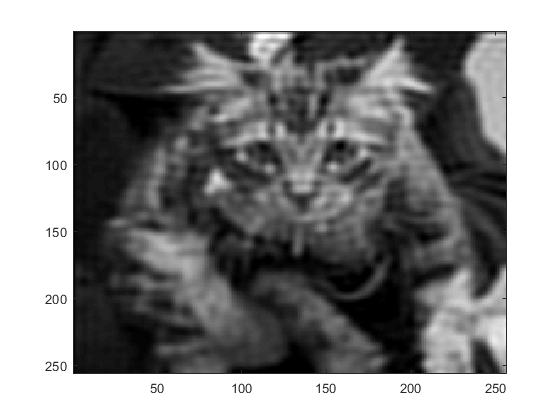


%View image
imagesc(uint8(inverse_transform))

14. Determine the compression ratio

%Count the number of entries in the compressed file
compressed_file = count_entry(compress)

cnt = 2850

compressed_file = 2850


%Count the number of entries in the uncompressed file
uncompressed_file = count_entry(Y)

cnt = 65536

uncompressed_file = 65536


%Calculate the compression ratio for p = 0.5
compress_ratio = uncompressed_file / compressed_file 

compress_ratio = 22.9951